%% TP3 - Diseño de un controlador adelanto-atraso
clear; clc; close all
s = tf('s');

Las figuras se guardan en: /home/ruben/Descargas/sistemas_de_control/imagenes


R1 = 100e3;  C1 = 0.1e-6;
R2 = 47e3;   C2 = 0.1e-6;
tau1 = R1*C1;                   
tau2 = R2*C2;                 
p1 = 1/tau1;                  
p2 = 1/tau2;                   
G = 1/((tau1*s + 1)*(tau2*s + 1));
G_zpk = zpk(G)                    


G_zpk =
 
        21277
  -----------------
  (s+212.8) (s+100)
 
Continuous-time zero/pole/gain model.



PO_max  = 5;                     
Ts_max  = 0.02;               
ess_max = 0.06;

zeta_min  = -log(PO_max/100)/sqrt(pi^2 + log(PO_max/100)^2);  
ang_max   = acosd(zeta_min);                                 
sigma_min = 4/Ts_max;                                       
Kp_min    = 1/ess_max - 1;                                  

fprintf('zeta_min  = %.4f  (ángulo máximo %.2f°)\n', zeta_min, ang_max)

zeta_min  = 0.6901  (ángulo máximo 46.36°)


fprintf('sigma_min = %.1f 1/s\n', sigma_min)

sigma_min = 200.0 1/s


fprintf('Kp_min    = %.3f\n', Kp_min)

Kp_min    = 15.667



fprintf('Sin compensar: parte real de los polos = -%.2f  (hace falta -%.0f o más a la izquierda)\n', ...
        (p1 + p2)/2, sigma_min)

Sin compensar: parte real de los polos = -156.38  (hace falta -200 o más a la izquierda)


%% Polo deseado
zeta_d  = 0.70;                    
sigma_d = 220;                   
wn_d = sigma_d/zeta_d;           
wd_d = wn_d*sqrt(1 - zeta_d^2);   
s_d  = -sigma_d + 1j*wd_d;
fprintf('s_d = %.3f + j%.3f   (wn = %.2f rad/s)\n', real(s_d), imag(s_d), wn_d)

s_d = -220.000 + j224.445   (wn = 314.29 rad/s)



%% 1a.
th1 = rad2deg(angle(s_d + p1));    
th2 = rad2deg(angle(s_d + p2));    
phi = th1 + th2 - 180;          
fprintf('th1 = %.3f°, th2 = %.3f°  ->  déficit phi = %.2f°\n', th1, th2, phi)

th1 = 118.131°, th2 = 91.846°  ->  déficit phi = 29.98°


%% 1b. 
zl   = sigma_d;                  
th_z = rad2deg(angle(s_d + zl));   
th_p = th_z - phi;                 
pl   = sigma_d + wd_d/tand(th_p); 
Gc   = (s + zl)/(s + pl);       
fprintf('th_z = %.2f°, th_p = %.2f°  ->  zl = %.2f, pl = %.2f\n', th_z, th_p, zl, pl)

th_z = 90.00°, th_p = 60.02°  ->  zl = 220.00, pl = 349.47



%% 1c. 
Ka = 1/abs(evalfr(Gc*G, s_d));   
fprintf('Ka = %.4f\n', Ka)

Ka = 3.1010



L_ad_sd = evalfr(Ka*Gc*G, s_d);
fprintf('Control: |L(s_d)| = %.4f, ángulo = %.2f°  (tiene que dar 1 y ±180°)\n', ...
        abs(L_ad_sd), rad2deg(angle(L_ad_sd)))

Control: |L(s_d)| = 1.0000, ángulo = -180.00°  (tiene que dar 1 y ±180°)



%% Implementación de K_a con R7 y R9 (K_a = 1 + R7/R9)
E24 = [1.0 1.1 1.2 1.3 1.5 1.6 1.8 2.0 2.2 2.4 2.7 3.0 3.3 3.6 3.9 4.3 ...
       4.7 5.1 5.6 6.2 6.8 7.5 8.2 9.1];
[R7_m, R9_m] = meshgrid([E24*1e3, E24*1e4], E24*1e3);  
Ka_m = 1 + R7_m./R9_m;
[~, orden] = sort(abs(Ka_m(:) - Ka));
orden = orden(1:5);
tabla_R = table(R7_m(orden)/1e3, R9_m(orden)/1e3, Ka_m(orden), ...
                'VariableNames', {'R7_kOhm', 'R9_kOhm', 'Ka'})

tabla_R = 5×3 table
    R7_kOhm    R9_kOhm      Ka  
    _______    _______    ______

      8.2        3.9      3.1026
       13        6.2      3.0968
      9.1        4.3      3.1163
      7.5        3.6      3.0833
      5.1        2.4       3.125


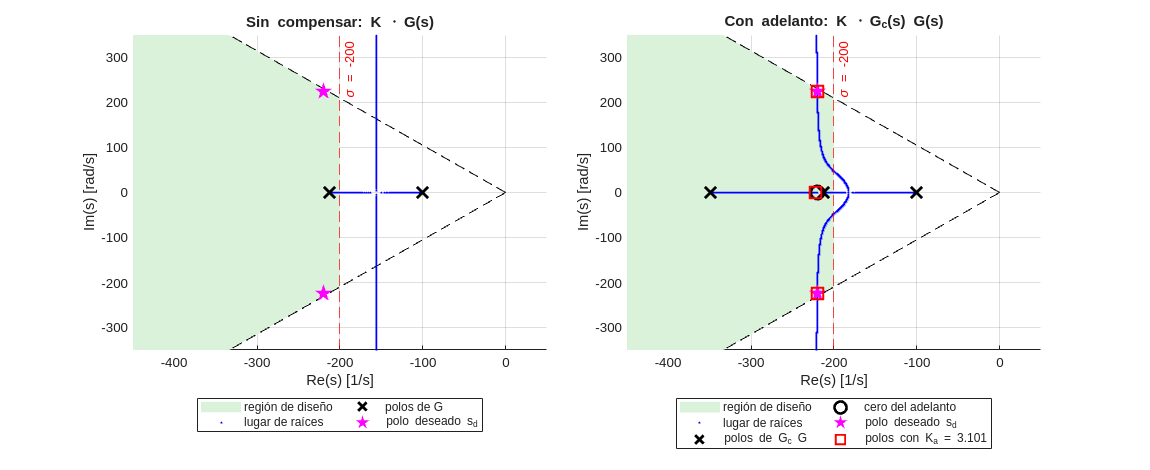

Figura guardada: /home/ruben/Descargas/sistemas_de_control/imagenes/TP3_1_lugar_raices.png


K_barrido = [linspace(0, 10, 4000), logspace(1, 3, 800)];
r_sin    = lugar_raices(G, K_barrido);
r_ad     = lugar_raices(Gc*G, K_barrido);
polos_ad = pole(feedback(Ka*Gc*G, 1));

nueva_figura([100 100 1150 470]);
tiledlayout(1, 2, 'TileSpacing', 'compact')

nexttile
dibujar_region(zeta_min, sigma_min, -450, 350)
plot(real(r_sin(:)), imag(r_sin(:)), 'b.', 'MarkerSize', 4, 'DisplayName', 'lugar de raíces')
plot([-p1 -p2], [0 0], 'kx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'polos de G')
plot(real([s_d conj(s_d)]), imag([s_d conj(s_d)]), 'mp', 'MarkerSize', 12, ...
     'MarkerFaceColor', 'm', 'DisplayName', 'polo deseado s_d')
xlim([-450 50]); ylim([-350 350])
title('Sin compensar: K \cdot G(s)')
legend('Location', 'southoutside', 'NumColumns', 2)

nexttile
dibujar_region(zeta_min, sigma_min, -450, 350)
plot(real(r_ad(:)), imag(r_ad(:)), 'b.', 'MarkerSize', 4, 'DisplayName', 'lugar de raíces')
plot([-p1 -p2 -pl], [0 0 0], 'kx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'polos de G_c G')
plot(-zl, 0, 'ko', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'cero del adelanto')
plot(real([s_d conj(s_d)]), imag([s_d conj(s_d)]), 'mp', 'MarkerSize', 12, ...
     'MarkerFaceColor', 'm', 'DisplayName', 'polo deseado s_d')
plot(real(polos_ad), imag(polos_ad), 'rs', 'MarkerSize', 11, 'LineWidth', 2, ...
     'DisplayName', "polos con K_a = " + round(Ka, 3))
xlim([-450 50]); ylim([-350 350])
title('Con adelanto: K \cdot G_c(s) G(s)')
legend('Location', 'southoutside', 'NumColumns', 2)

guardar("TP3_1_lugar_raices")

polos_ad

polos_ad = 1.0e+02 *

  -2.2000 + 2.2444i
  -2.2000 - 2.2444i
  -2.2223 + 0.0000i


%% 2a. 
L_ad = Ka*Gc*G;                      
T_ad = feedback(L_ad, 1);           
T_ad_zpk = zpk(T_ad)


T_ad_zpk =
 
            65980 (s+220)
  ---------------------------------
  (s+222.2) (s^2 + 440s + 9.878e04)
 
Continuous-time zero/pole/gain model.



t_ad  = (0:1e-6:0.06)';                 
y_ad  = step(T_ad, t_ad);
yf_ad = dcgain(T_ad);                  
info_ad = stepinfo(y_ad, t_ad, yf_ad); 

Kp_ad  = dcgain(L_ad);                 
ess_ad = 1/(1 + Kp_ad);

fprintf('PO = %.2f %%  (pico %.4f a los %.2f ms)\n', info_ad.Overshoot, info_ad.Peak, 1e3*info_ad.PeakTime)

PO = 4.78 %  (pico 0.6929 a los 13.91 ms)


fprintf('Ts = %.2f ms\n', 1e3*info_ad.SettlingTime)

Ts = 19.09 ms


fprintf('y_final = %.4f,  Kp = %.4f,  ess = %.4f\n', yf_ad, Kp_ad, ess_ad)

y_final = 0.6613,  Kp = 1.9522,  ess = 0.3387


[num_ad, den_ad] = tfdata(T_ad, 'v');
[res_ad, polos_res_ad] = residue(num_ad, conv(den_ad, [1 0]));
tabla_residuos_ad = table(polos_res_ad, abs(res_ad), rad2deg(angle(res_ad)), ...
                          'VariableNames', {'polo', 'modulo_residuo', 'angulo_grados'})

tabla_residuos_ad = 4×3 table
         polo          modulo_residuo    angulo_grados
    _______________    ______________    _____________

       -220+224.44i        0.46765           136.14   
       -220-224.44i        0.46765          -136.14   
    -222.23+0i            0.013147                0   
          0+0i             0.66127                0   


y_mano_ad = 0.6613 + 0.0131*exp(-222.23*t_ad) ...
          + 0.9353*exp(-220*t_ad).*cos(224.445*t_ad + deg2rad(136.14));
fprintf('Diferencia máxima entre step() y la fórmula a mano: %.1e\n', max(abs(y_ad - y_mano_ad)))

Diferencia máxima entre step() y la fórmula a mano: 2.9e-05


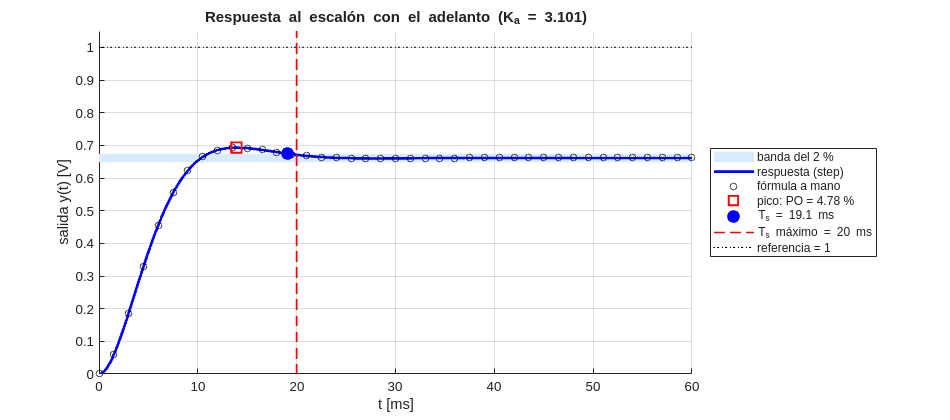

Figura guardada: /home/ruben/Descargas/sistemas_de_control/imagenes/TP3_2a_escalon_adelanto.png



%% Figura del punto 2a
nueva_figura([100 100 950 420]);
banda = [0.98 1.02]*yf_ad;
patch([0 60 60 0], [banda(1) banda(1) banda(2) banda(2)], [0.85 0.92 1], ...
      'EdgeColor', 'none', 'DisplayName', 'banda del 2 %')
hold on
plot(1e3*t_ad, y_ad, 'b', 'LineWidth', 2, 'DisplayName', 'respuesta (step)')
plot(1e3*t_ad(1:1500:end), y_mano_ad(1:1500:end), 'ko', 'MarkerSize', 5, ...
     'DisplayName', 'fórmula a mano')
plot(1e3*info_ad.PeakTime, info_ad.Peak, 'rs', 'MarkerSize', 10, 'LineWidth', 2, ...
     'DisplayName', "pico: PO = " + round(info_ad.Overshoot, 2) + " %")
plot(1e3*info_ad.SettlingTime, interp1(t_ad, y_ad, info_ad.SettlingTime), 'bo', ...
     'MarkerSize', 9, 'MarkerFaceColor', 'b', ...
     'DisplayName', "T_s = " + round(1e3*info_ad.SettlingTime, 1) + " ms")
plot([20 20], [0 1.05], 'r--', 'LineWidth', 1.2, 'DisplayName', 'T_s máximo = 20 ms')
plot([0 60], [1 1], 'k:', 'DisplayName', 'referencia = 1')
grid on
xlim([0 60]); ylim([0 1.05])
xlabel('t [ms]'); ylabel('salida y(t) [V]')
title("Respuesta al escalón con el adelanto (K_a = " + round(Ka, 3) + ")")
legend('Location', 'eastoutside')
guardar("TP3_2a_escalon_adelanto")


%% 2b.
especificacion = ["PO <= 5 %"; "Ts <= 20 ms"; "ess <= 0,06"];
valor  = [info_ad.Overshoot; 1e3*info_ad.SettlingTime; ess_ad];
cumple = [info_ad.Overshoot <= PO_max; info_ad.SettlingTime <= Ts_max; ess_ad <= ess_max];
tabla_2b = table(especificacion, valor, cumple)

tabla_2b = 3×3 table
    especificacion     valor     cumple
    ______________    _______    ______

    "PO <= 5 %"        4.7806    true  
    "Ts <= 20 ms"      19.091    true  
    "ess <= 0,06"     0.33873    false 


%% 3a.
alfa_min = Kp_min/Kp_ad;         
alfa = 10;                        
fprintf('alfa mínimo = %.3f  ->  elegimos alfa = %d\n', alfa_min, alfa)

alfa mínimo = 8.025  ->  elegimos alfa = 10


fprintf('Kp final = %.3f,  ess esperado = %.4f\n', alfa*Kp_ad, 1/(1 + alfa*Kp_ad))

Kp final = 19.522,  ess esperado = 0.0487


%% 3b.
za_prueba = [5 10 20 30 40 50 60 70 75 78 80 85 88 90 95];
n = numel(za_prueba);
[ang_sd, mod_sd, polo_lento, zeta_dom, sigma_dom, PO_za, Ts_za] = deal(zeros(n, 1));
t_largo = (0:2e-6:1)';
for i = 1:n
    za_i  = za_prueba(i);
    Gca_i = (s + za_i)/(s + za_i/alfa);
    ang_sd(i) = rad2deg(angle(evalfr(Gca_i, s_d)));   
    mod_sd(i) = abs(evalfr(Gca_i, s_d));              
    T_i = feedback(Ka*Gca_i*Gc*G, 1);
    p_i = pole(T_i);
    polo_lento(i) = max(real(p_i(abs(imag(p_i)) < 1e-6)));
    [~, k] = max(imag(p_i));                        
    zeta_dom(i)  = -real(p_i(k))/abs(p_i(k));
    sigma_dom(i) = -real(p_i(k));
    info_i   = stepinfo(step(T_i, t_largo), t_largo, dcgain(T_i));
    PO_za(i) = info_i.Overshoot;
    Ts_za(i) = 1e3*info_i.SettlingTime;
end
en_region   = (zeta_dom >= zeta_min) & (sigma_dom >= sigma_min);
cumple_todo = (PO_za <= PO_max) & (Ts_za <= 1e3*Ts_max);
tabla_za = table(za_prueba', za_prueba'/alfa, ang_sd, mod_sd, polo_lento, zeta_dom, ...
                 sigma_dom, en_region, PO_za, Ts_za, cumple_todo, ...
                 'VariableNames', {'za', 'pa', 'angulo_en_sd', 'modulo_en_sd', 'polo_lento', ...
                 'zeta_dom', 'sigma_dom', 'dominantes_en_region', 'PO', 'Ts_ms', 'cumple_PO_y_Ts'})

tabla_za = 15×11 table
    za    pa     angulo_en_sd    modulo_en_sd    polo_lento    zeta_dom    sigma_dom    dominantes_en_region        PO        Ts_ms     cumple_PO_y_Ts
    __    ___    ____________    ____________    __________    ________    _________    ____________________    __________    ______    ______________

     5    0.5      -0.59309        0.99003        -3.5223      0.69983      218.46             true                      0    769.02        false     
    10      1       -1.2009        0.98017        -7.1416       0.6996      216.87             true                      0    376.88        false     
    20      2       -2.4616         0.9608        -14.698      0.69895      213.52             true                      0    180.35        false     
    30      3       -3.7848        0.94194        -22.728      0.69796      209.92             true                      0    114.34        false     
    40      4       -5.1727        0.92362        -31.302      0.69655

za_lim_angulo = interp1(ang_sd, za_prueba, -5);          
za_lim_region = interp1(sigma_dom, za_prueba, sigma_min); 
fprintf('Regla del ángulo (5°): za <= %.1f\n', za_lim_angulo)

Regla del ángulo (5°): za <= 38.8


fprintf('Polos dominantes en la región: za <= %.1f\n', za_lim_region)

Polos dominantes en la región: za <= 54.0


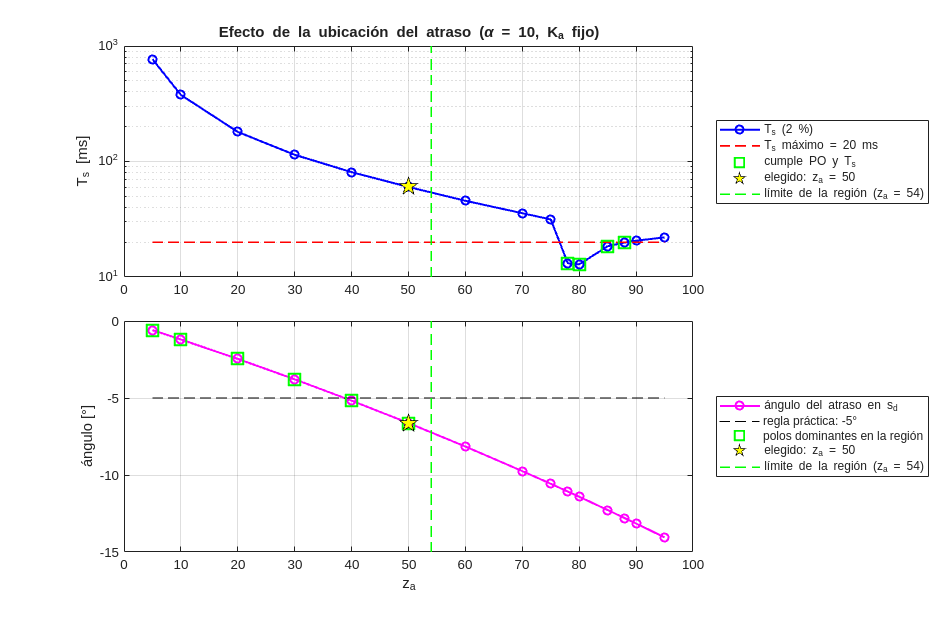

Figura guardada: /home/ruben/Descargas/sistemas_de_control/imagenes/TP3_3_eleccion_za.png


nueva_figura([100 100 950 620]);
tiledlayout(2, 1, 'TileSpacing', 'compact')

nexttile
semilogy(za_prueba, Ts_za, 'bo-', 'LineWidth', 1.5, 'DisplayName', 'T_s (2 %)')
hold on
plot(za_prueba([1 end]), [20 20], 'r--', 'LineWidth', 1.2, 'DisplayName', 'T_s máximo = 20 ms')
plot(za_prueba(cumple_todo), Ts_za(cumple_todo), 'gs', 'MarkerSize', 11, 'LineWidth', 2, ...
     'DisplayName', 'cumple PO y T_s')
plot(50, Ts_za(za_prueba == 50), 'kp', 'MarkerSize', 14, 'MarkerFaceColor', 'y', ...
     'DisplayName', 'elegido: z_a = 50')
plot(za_lim_region*[1 1], [10 1000], 'g--', 'LineWidth', 1.2, ...
     'DisplayName', "límite de la región (z_a = " + round(za_lim_region, 1) + ")")
grid on
ylabel('T_s [ms]')
title('Efecto de la ubicación del atraso (\alpha = 10, K_a fijo)')
legend('Location', 'eastoutside')

nexttile
plot(za_prueba, ang_sd, 'mo-', 'LineWidth', 1.5, 'DisplayName', 'ángulo del atraso en s_d')
hold on
plot(za_prueba([1 end]), [-5 -5], 'k--', 'DisplayName', 'regla práctica: -5°')
plot(za_prueba(en_region), ang_sd(en_region), 'gs', 'MarkerSize', 11, 'LineWidth', 2, ...
     'DisplayName', 'polos dominantes en la región')
plot(50, ang_sd(za_prueba == 50), 'kp', 'MarkerSize', 14, 'MarkerFaceColor', 'y', ...
     'DisplayName', 'elegido: z_a = 50')
plot(za_lim_region*[1 1], [-15 0], 'g--', 'LineWidth', 1.2, ...
     'DisplayName', "límite de la región (z_a = " + round(za_lim_region, 1) + ")")
grid on
xlabel('z_a'); ylabel('ángulo [°]')
legend('Location', 'eastoutside')
guardar("TP3_3_eleccion_za")

%% Atraso elegido
za = 50;
pa = za/alfa;                         
Gca = (s + za)/(s + pa);
Gca_sd = evalfr(Gca, s_d);
fprintf('Atraso: za = %g, pa = %g\n', za, pa)

Atraso: za = 50, pa = 5


fprintf('En s_d el atraso vale: módulo %.3f, ángulo %.2f°\n', abs(Gca_sd), rad2deg(angle(Gca_sd)))

En s_d el atraso vale: módulo 0.906, ángulo -6.63°



%% Figura: lugar de raíces con adelanto y atraso
K_barrido2 = [linspace(0, 10, 6000), logspace(1, 3, 800)];
r_fin     = lugar_raices(Gca*Gc*G, K_barrido2);
polos_fin = pole(feedback(Ka*Gca*Gc*G, 1))

polos_fin = 1.0e+02 *

  -2.0183 + 2.0906i
  -2.0183 - 2.0906i
  -2.2306 + 0.0000i
  -0.4051 + 0.0000i


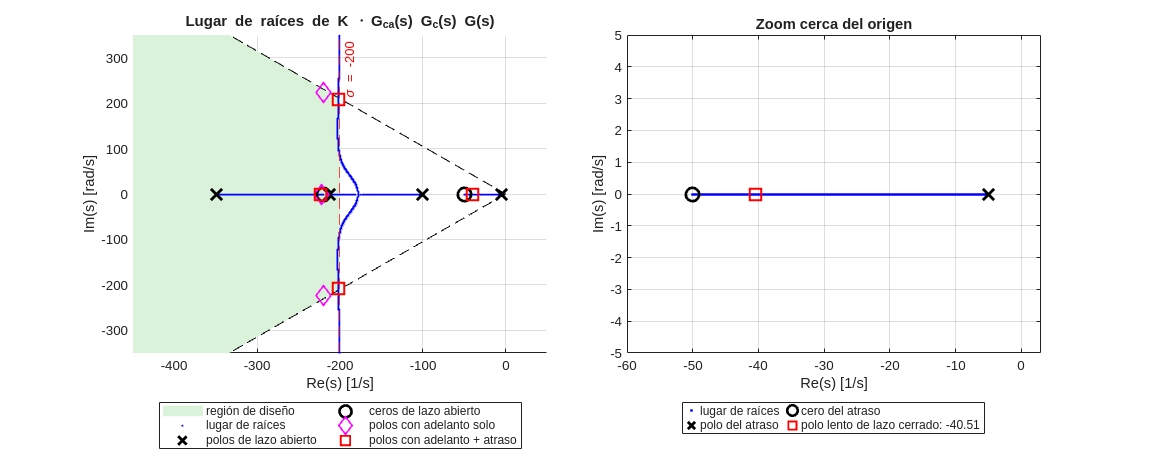

Figura guardada: /home/ruben/Descargas/sistemas_de_control/imagenes/TP3_3_lugar_raices_final.png


p_lento   = max(real(polos_fin(abs(imag(polos_fin)) < 1e-6)));

nueva_figura([100 100 1150 470]);
tiledlayout(1, 2, 'TileSpacing', 'compact')

nexttile
dibujar_region(zeta_min, sigma_min, -450, 350)
plot(real(r_fin(:)), imag(r_fin(:)), 'b.', 'MarkerSize', 4, 'DisplayName', 'lugar de raíces')
plot([-p1 -p2 -pl -pa], [0 0 0 0], 'kx', 'MarkerSize', 12, 'LineWidth', 2, ...
     'DisplayName', 'polos de lazo abierto')
plot([-zl -za], [0 0], 'ko', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'ceros de lazo abierto')
plot(real(polos_ad), imag(polos_ad), 'md', 'MarkerSize', 10, 'LineWidth', 1.5, ...
     'DisplayName', 'polos con adelanto solo')
plot(real(polos_fin), imag(polos_fin), 'rs', 'MarkerSize', 11, 'LineWidth', 2, ...
     'DisplayName', 'polos con adelanto + atraso')
xlim([-450 50]); ylim([-350 350])
title('Lugar de raíces de K \cdot G_{ca}(s) G_c(s) G(s)')
legend('Location', 'southoutside', 'NumColumns', 2)

nexttile
plot(real(r_fin(:)), imag(r_fin(:)), 'b.', 'MarkerSize', 6, 'DisplayName', 'lugar de raíces')
hold on
plot(-pa, 0, 'kx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'polo del atraso')
plot(-za, 0, 'ko', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'cero del atraso')
plot(p_lento, 0, 'rs', 'MarkerSize', 11, 'LineWidth', 2, ...
     'DisplayName', "polo lento de lazo cerrado: " + round(p_lento, 2))
grid on
xlim([-60 3]); ylim([-5 5])
xlabel('Re(s) [1/s]'); ylabel('Im(s) [rad/s]')
title('Zoom cerca del origen')
legend('Location', 'southoutside', 'NumColumns', 2)
guardar("TP3_3_lugar_raices_final")

%% 4.
G_total = Ka*Gca*Gc;           
L_fin   = G_total*G;               
Sys_c   = feedback(L_fin, 1);        
Sys_c_zpk = zpk(Sys_c)


Sys_c_zpk =
 
              65980 (s+220) (s+50)
  ---------------------------------------------
  (s+223.1) (s+40.51) (s^2 + 403.7s + 8.444e04)
 
Continuous-time zero/pole/gain model.


[num_c, den_c] = tfdata(Sys_c, 'v');
num_c = num_c/den_c(1);  den_c = den_c/den_c(1); 
fprintf('Numerador:   '); fprintf('%.6g   ', num_c); fprintf('\n')

Numerador:   0   0   65979.8   1.78145e+07   7.25778e+08   


fprintf('Denominador: '); fprintf('%.6g   ', den_c); fprintf('\n')

Denominador: 1   667.231   199868   2.59029e+07   7.62955e+08   


polos_c    = pole(Sys_c);
polos_mano = [-201.83 + 209.06j; -201.83 - 209.06j; -223.06; -40.51];
tabla_polos = table(polos_c, polos_mano, 'VariableNames', {'MATLAB', 'a_mano'})

tabla_polos = 4×2 table
        MATLAB             a_mano     
    _______________    _______________

    -201.83+209.06i    -201.83+209.06i
    -201.83-209.06i    -201.83-209.06i
    -223.06+0i         -223.06+0i     
    -40.507+0i          -40.51+0i     



%% 4a.
t_c  = (0:1e-6:0.15)';         
y_c  = step(Sys_c, t_c);
yf_c = dcgain(Sys_c);
info_c = stepinfo(y_c, t_c, yf_c);

fprintf('PO = %.2f %%\n', info_c.Overshoot)

PO = 0.00 %


fprintf('Ts = %.2f ms\n', 1e3*info_c.SettlingTime)

Ts = 60.21 ms


fprintf('y_final = %.4f\n', yf_c)

y_final = 0.9513


fprintf('A los 20 ms la salida vale %.4f (%.1f %% del valor final)\n', ...
        interp1(t_c, y_c, 0.02), 100*interp1(t_c, y_c, 0.02)/yf_c)

A los 20 ms la salida vale 0.8726 (91.7 % del valor final)


en_20ms = t_c <= 0.02;
[y_bulto, i_bulto] = max(y_c(en_20ms));
t_bulto = t_c(i_bulto);
fprintf('Máximo local: %.4f a los %.2f ms\n', y_bulto, 1e3*t_bulto)

Máximo local: 0.8743 a los 17.41 ms


[res_c, polos_res_c] = residue(num_c, conv(den_c, [1 0]));
tabla_residuos_c = table(polos_res_c, abs(res_c), rad2deg(angle(res_c)), ...
                         'VariableNames', {'polo', 'modulo_residuo', 'angulo_grados'})

tabla_residuos_c = 5×3 table
         polo          modulo_residuo    angulo_grados
    _______________    ______________    _____________

    -201.83+209.06i        0.53063           135.17   
    -201.83-209.06i        0.53063          -135.17   
    -223.06+0i            0.019415                0   
    -40.507+0i             0.21804              180   
          0+0i             0.95127                0   



y_mano_c = 0.9513 - 0.2180*exp(-40.51*t_c) + 0.0194*exp(-223.06*t_c) ...
         + 1.0613*exp(-201.83*t_c).*cos(209.06*t_c + deg2rad(135.17));
fprintf('Diferencia máxima entre step() y la fórmula a mano: %.1e\n', max(abs(y_c - y_mano_c)))

Diferencia máxima entre step() y la fórmula a mano: 5.9e-05


[~, j] = min(abs(polos_res_c - p_lento));
res_lento = real(res_c(j));
Ts_cola = log(abs(res_lento)/(0.02*yf_c))/abs(p_lento);
fprintf('Ts predicho con la cola = %.2f ms\n', 1e3*Ts_cola)

Ts predicho con la cola = 60.21 ms


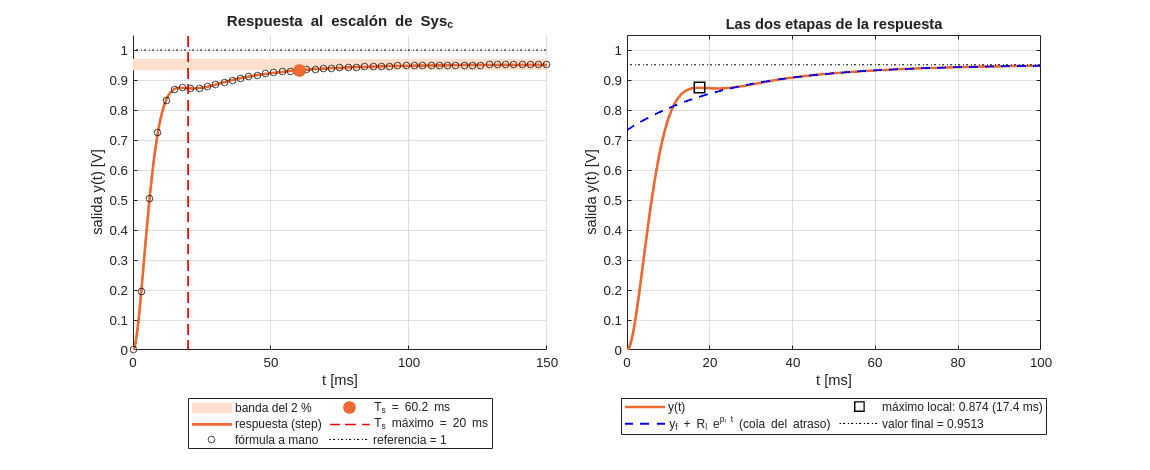

Figura guardada: /home/ruben/Descargas/sistemas_de_control/imagenes/TP3_4a_escalon_final.png



%% Figura del punto 4a
naranja = [0.92 0.41 0.20];
nueva_figura([100 100 1150 470]);
tiledlayout(1, 2, 'TileSpacing', 'compact')

nexttile
banda_c = [0.98 1.02]*yf_c;
patch([0 150 150 0], [banda_c(1) banda_c(1) banda_c(2) banda_c(2)], [1 0.88 0.80], ...
      'EdgeColor', 'none', 'DisplayName', 'banda del 2 %')
hold on
plot(1e3*t_c, y_c, 'Color', naranja, 'LineWidth', 2, 'DisplayName', 'respuesta (step)')
plot(1e3*t_c(1:3000:end), y_mano_c(1:3000:end), 'ko', 'MarkerSize', 5, ...
     'DisplayName', 'fórmula a mano')
plot(1e3*info_c.SettlingTime, interp1(t_c, y_c, info_c.SettlingTime), 'o', 'Color', naranja, ...
     'MarkerFaceColor', naranja, 'MarkerSize', 9, ...
     'DisplayName', "T_s = " + round(1e3*info_c.SettlingTime, 1) + " ms")
plot([20 20], [0 1.05], 'r--', 'LineWidth', 1.2, 'DisplayName', 'T_s máximo = 20 ms')
plot([0 150], [1 1], 'k:', 'DisplayName', 'referencia = 1')
grid on
xlim([0 150]); ylim([0 1.05])
xlabel('t [ms]'); ylabel('salida y(t) [V]')
title('Respuesta al escalón de Sys_c')
legend('Location', 'southoutside', 'NumColumns', 2)

nexttile
cola = yf_c + res_lento*exp(p_lento*t_c); 
plot(1e3*t_c, y_c, 'Color', naranja, 'LineWidth', 2, 'DisplayName', 'y(t)')
hold on
plot(1e3*t_c, cola, 'b--', 'LineWidth', 1.5, 'DisplayName', 'y_f + R_l e^{p_l t} (cola del atraso)')
plot(1e3*t_bulto, y_bulto, 'ks', 'MarkerSize', 10, 'LineWidth', 1.5, ...
     'DisplayName', "máximo local: " + round(y_bulto, 3) + " (" + round(1e3*t_bulto, 1) + " ms)")
plot([0 100], yf_c*[1 1], 'k:', 'DisplayName', "valor final = " + round(yf_c, 4))
grid on
xlim([0 100]); ylim([0 1.05])
xlabel('t [ms]'); ylabel('salida y(t) [V]')
title('Las dos etapas de la respuesta')
legend('Location', 'southoutside', 'NumColumns', 2)
guardar("TP3_4a_escalon_final")


%% 4b.
ess_c_1 = 1 - yf_c;                   
Kp_c    = dcgain(L_fin);           
ess_c_2 = 1/(1 + Kp_c);            
fprintf('Kp = G(0) * Ka*zl/pl * za/pa = %.4f * %.4f * %g = %.3f\n', ...
        dcgain(G), Ka*zl/pl, za/pa, Kp_c)

Kp = G(0) * Ka*zl/pl * za/pa = 1.0000 * 1.9522 * 10 = 19.522


fprintf('ess = 1 - y_f = %.4f   |   ess = 1/(1 + Kp) = %.4f\n', ess_c_1, ess_c_2)

ess = 1 - y_f = 0.0487   |   ess = 1/(1 + Kp) = 0.0487



valor_c  = [info_c.Overshoot; 1e3*info_c.SettlingTime; ess_c_1];
cumple_c = [info_c.Overshoot <= PO_max; info_c.SettlingTime <= Ts_max; ess_c_1 <= ess_max];
tabla_4b = table(especificacion, valor_c, cumple_c)

tabla_4b = 3×3 table
    especificacion    valor_c     cumple_c
    ______________    ________    ________

    "PO <= 5 %"              0     true   
    "Ts <= 20 ms"       60.214     false  
    "ess <= 0,06"     0.048728     true   



%% 5.
T_sin = feedback(G, 1);
t5 = (0:1e-6:0.15)';

sistemas = {T_sin, T_ad, Sys_c};
nombres  = ["Sin compensar"; "Adelanto"; "Adelanto + atraso"];
[PO5, Ts5, yf5, ess5] = deal(zeros(3, 1));
for i = 1:3
    yf5(i)  = dcgain(sistemas{i});
    info5   = stepinfo(step(sistemas{i}, t5), t5, yf5(i));
    PO5(i)  = info5.Overshoot;
    Ts5(i)  = 1e3*info5.SettlingTime;
    ess5(i) = 1 - yf5(i);
end
tabla_5 = table(nombres, PO5, Ts5, yf5, ess5, PO5 <= PO_max, Ts5 <= 1e3*Ts_max, ess5 <= ess_max, ...
                'VariableNames', {'sistema', 'PO', 'Ts_ms', 'y_final', 'ess', ...
                                  'cumple_PO', 'cumple_Ts', 'cumple_ess'})

tabla_5 = 3×8 table
          sistema            PO      Ts_ms     y_final      ess       cumple_PO    cumple_Ts    cumple_ess
    ___________________    ______    ______    _______    ________    _________    _________    __________

    "Sin compensar"        2.5939    27.434        0.5         0.5      true         false        false   
    "Adelanto"             4.7806    19.091    0.66127     0.33873      true         true         false   
    "Adelanto + atraso"         0    60.214    0.95127    0.048728      true         false        true    


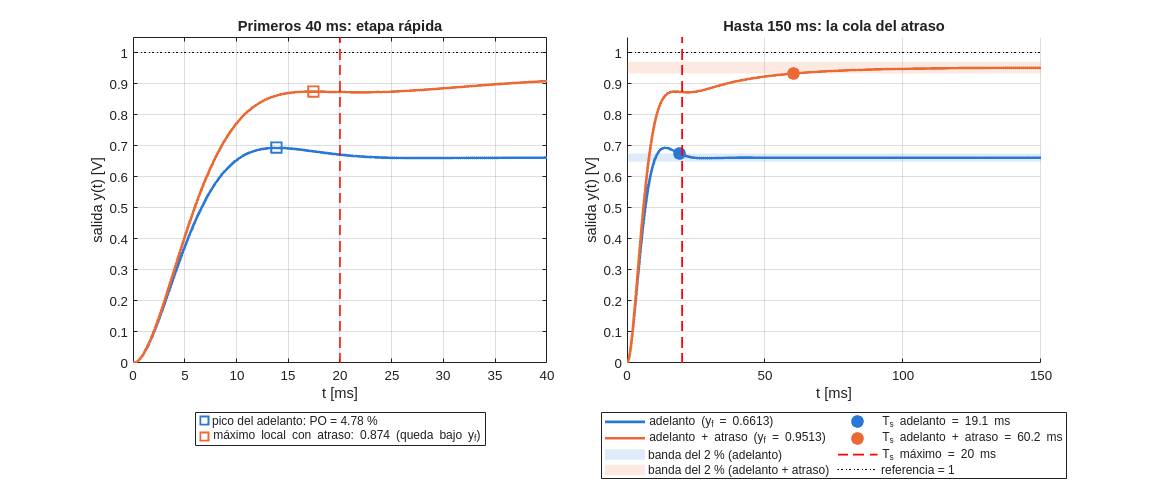

Figura guardada: /home/ruben/Descargas/sistemas_de_control/imagenes/TP3_5_comparacion.png



y_ad5 = step(T_ad, t5);
y_c5  = step(Sys_c, t5);
azul    = [0.16 0.47 0.84];
naranja = [0.92 0.41 0.20];

nueva_figura([100 100 1150 500]);
tiledlayout(1, 2, 'TileSpacing', 'compact')

nexttile
plot(1e3*t5, y_ad5, 'Color', azul, 'LineWidth', 2)
hold on
plot(1e3*t5, y_c5, 'Color', naranja, 'LineWidth', 2)
plot([20 20], [0 1.05], 'r--', 'LineWidth', 1.2)
plot([0 40], [1 1], 'k:')
h_pico  = plot(1e3*info_ad.PeakTime, info_ad.Peak, 's', 'Color', azul, 'MarkerSize', 10, ...
               'LineWidth', 2, 'DisplayName', "pico del adelanto: PO = " + round(info_ad.Overshoot, 2) + " %");
h_bulto = plot(1e3*t_bulto, y_bulto, 's', 'Color', naranja, 'MarkerSize', 10, 'LineWidth', 2, ...
               'DisplayName', "máximo local con atraso: " + round(y_bulto, 3) + " (queda bajo y_f)");
grid on
xlim([0 40]); ylim([0 1.05])
xlabel('t [ms]'); ylabel('salida y(t) [V]')
title('Primeros 40 ms: etapa rápida')
legend([h_pico h_bulto], 'Location', 'southoutside')

nexttile
h_b1 = patch([0 150 150 0], yf5(2)*[0.98 0.98 1.02 1.02], azul, 'FaceAlpha', 0.15, ...
             'EdgeColor', 'none', 'DisplayName', 'banda del 2 % (adelanto)');
hold on
h_b2 = patch([0 150 150 0], yf5(3)*[0.98 0.98 1.02 1.02], naranja, 'FaceAlpha', 0.15, ...
             'EdgeColor', 'none', 'DisplayName', 'banda del 2 % (adelanto + atraso)');
h_ad = plot(1e3*t5, y_ad5, 'Color', azul, 'LineWidth', 2, ...
            'DisplayName', "adelanto (y_f = " + round(yf5(2), 4) + ")");
h_c  = plot(1e3*t5, y_c5, 'Color', naranja, 'LineWidth', 2, ...
            'DisplayName', "adelanto + atraso (y_f = " + round(yf5(3), 4) + ")");
h_t1 = plot(Ts5(2), interp1(t5, y_ad5, Ts5(2)/1e3), 'o', 'Color', azul, 'MarkerFaceColor', azul, ...
            'MarkerSize', 9, 'DisplayName', "T_s adelanto = " + round(Ts5(2), 1) + " ms");
h_t2 = plot(Ts5(3), interp1(t5, y_c5, Ts5(3)/1e3), 'o', 'Color', naranja, 'MarkerFaceColor', naranja, ...
            'MarkerSize', 9, 'DisplayName', "T_s adelanto + atraso = " + round(Ts5(3), 1) + " ms");
h_lim = plot([20 20], [0 1.05], 'r--', 'LineWidth', 1.2, 'DisplayName', 'T_s máximo = 20 ms');
h_ref = plot([0 150], [1 1], 'k:', 'DisplayName', 'referencia = 1');
grid on
xlim([0 150]); ylim([0 1.05])
xlabel('t [ms]'); ylabel('salida y(t) [V]')
title('Hasta 150 ms: la cola del atraso')
legend([h_ad h_c h_b1 h_b2 h_t1 h_t2 h_lim h_ref], 'Location', 'southoutside', 'NumColumns', 2)
guardar("TP3_5_comparacion")

function raices = lugar_raices(L0, K)
    [num, den] = tfdata(L0, 'v');
    num = [zeros(1, numel(den) - numel(num)), num];
    raices = zeros(numel(den) - 1, numel(K));
    for j = 1:numel(K)
        raices(:, j) = roots(den + K(j)*num);
    end
end

function dibujar_region(zeta_min, sigma_min, x_izq, y_max)
    tg = tan(acos(zeta_min));
    x = linspace(-sigma_min, x_izq, 200);
    y_sup = min(-x*tg, y_max);
    patch([x, fliplr(x)], [y_sup, -fliplr(y_sup)], [0.85 0.95 0.85], ...
          'EdgeColor', 'none', 'DisplayName', 'región de diseño')
    hold on
    plot([0, x_izq], [0, -x_izq*tg], 'k--', 'HandleVisibility', 'off')
    plot([0, x_izq], [0,  x_izq*tg], 'k--', 'HandleVisibility', 'off')
    xline(-sigma_min, 'r--', "\sigma = -" + sigma_min, 'HandleVisibility', 'off')
    grid on
    xlabel('Re(s) [1/s]'); ylabel('Im(s) [rad/s]')
end

function fig = nueva_figura(posicion)
    fig = figure('Position', posicion, 'Color', 'w');
    if ~isMATLABReleaseOlderThan("R2025a")
        theme(fig, "light");
    end
end

function guardar(nombre)
    carpeta = fullfile(pwd, "imagenes");
    if ~isfolder(carpeta), mkdir(carpeta); end
    archivo = fullfile(carpeta, nombre + ".png");
    exportgraphics(gcf, archivo, 'Resolution', 200, 'BackgroundColor', 'white')
    fprintf('Figura guardada: %s\n', archivo)
end